#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# 2D Signals

Of course, for imaging, most of our signals are 2D (or even 3D), so it's worth taking a moment to think about how to work with 2D signals in MATLAB  

clc
close all
clear all

## 2D function index spaces

When dealing with 1D functions, e.g, $f(x)$, we often a vector of values of out independent variable, in this case, $x$. We can do this in MATLAB using notation such as `x = (0:1:10)';` or `x = linspace(0,10,11)';`. For 2D functions, such as $f(x,y)$ we need a 2D index spaces for *both* $x$ and $y$. That is, if our 2D function, $f$ is $N_\mathrm{x} \times N_\mathrm{y}$ in size, then so must both the index spaces $x$ and $y$. This is a bit confusion, but MATLAB has a handy function to help -- `meshgrid`.

% to create a 2D sample space, use meshgrid
help meshgrid

 meshgrid   Cartesian rectangular grid in 2-D or 3-D
    [X,Y] = meshgrid(x,y) returns 2-D grid coordinates based on the
    coordinates contained in vectors x and y. X is a matrix where each row
    is a copy of x, and Y is a matrix where each column is a copy of y. The
    grid represented by the coordinates X and Y has length(y) rows and
    length(x) columns.
 
    [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the
    vectors x, y, and z. The grid represented by X, Y, and Z has size
    length(y)-by-length(x)-by-length(z).
 
    [X,Y] = meshgrid(x) is the same as [X,Y] = meshgrid(x,x), returning
    square grid coordinates with grid size length(x)-by-length(x).
 
    [X,Y,Z] = meshgrid(x) is the same as [X,Y,Z] = meshgrid(x,x,x),
    returning 3-D grid coordinates with grid size
    length(x)-by-length(x)-by-length(x).
 
    meshgrid


% Example

Example:

Start by defing 1D index vectors, suitably sampling the $x$ and $y$ domains.

x = linspace(-2,2,5); % (mm) 
y = linspace(1,5,5); % (mm)

Now use meshgrid to create the corresponding 2D index spaces, $x2$ and $y2$ in this example

[x2,y2] = meshgrid(x,y) % no semicolon results in assignments echoed to screen

x2 =     -2.0000e+000    -1.0000e+000     0.0000e+000     1.0000e+000     2.0000e+000
    -2.0000e+000    -1.0000e+000     0.0000e+000     1.0000e+000     2.0000e+000
    -2.0000e+000    -1.0000e+000     0.0000e+000     1.0000e+000     2.0000e+000
    -2.0000e+000    -1.0000e+000     0.0000e+000     1.0000e+000     2.0000e+000
    -2.0000e+000    -1.0000e+000     0.0000e+000     1.0000e+000     2.0000e+000


y2 =      1.0000e+000     1.0000e+000     1.0000e+000     1.0000e+000     1.0000e+000
     2.0000e+000     2.0000e+000     2.0000e+000     2.0000e+000     2.0000e+000
     3.0000e+000     3.0000e+000     3.0000e+000     3.0000e+000     3.0000e+000
     4.0000e+000     4.0000e+000     4.0000e+000     4.0000e+000     4.0000e+000
     5.0000e+000     5.0000e+000     5.0000e+000     5.0000e+000     5.0000e+000


We see that both `x2` and `y2` are 5 x 5 matrices. For x2, each row has the same values and for y2 each column has the same value.

Try and example with more points.

% recreate with more sample points
Nx = 51;
Ny = 150;
x = linspace(-3,3,Nx); % (mm)
y = linspace(-3,5,Ny); % (mm)

[x2,y2] = meshgrid(x,y);


Now let's create a 2D sinc function. MALTAB doesn't have this function built-in, but it is super simple to make from 1D sinc functions

% 2D Sinc function
sinc2d = @(u,v)(sinc(u).*sinc(v))

sinc2d = function_handle with value:
    @(u,v)(sinc(u).*sinc(v))


f = sinc2d(x2,y2);

Plot it! In MATLAB, you can plot 2D functions in a number of ways -- mesh, surf, contour, ..., or, particularly relevant to this course, we can create an intensity image.

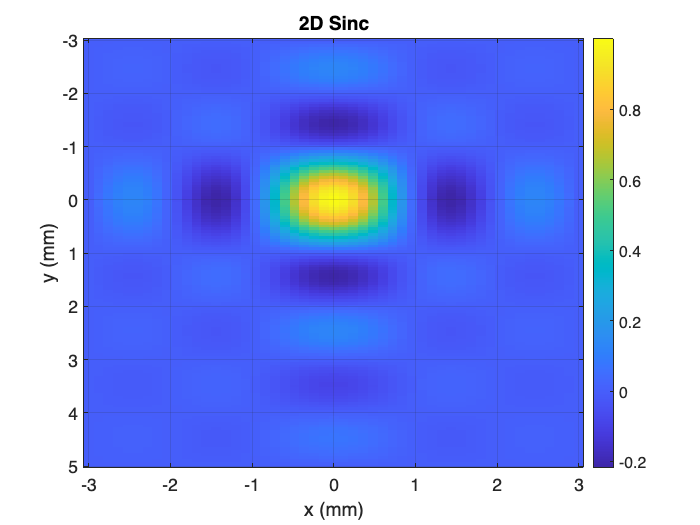

imagesc(x,y,f), colorbar
xlabel('x (mm)'), ylabel('y (mm)'),
title('2D Sinc');

See also `image`, `imshow`, and `imtool` for other image generating functions.

Note that this image looks a little distorted since the step size of index values is not the same in x- and y-directions. Use '`axis equal`' to set the aspect ratio to so that the distances in x- and y- match the indices

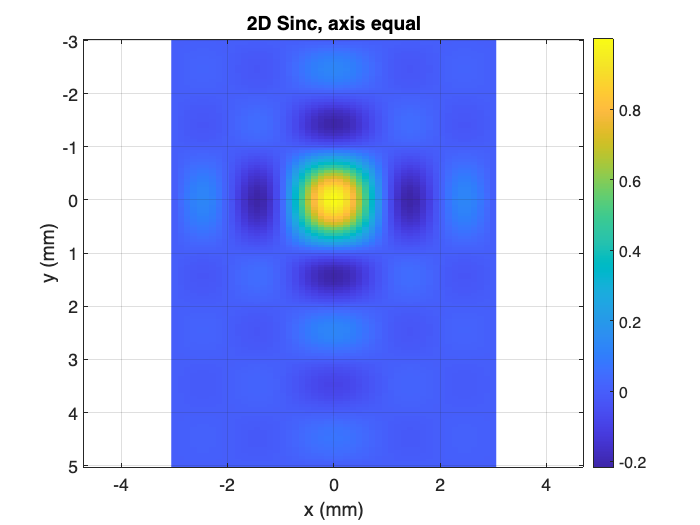

axis('equal')
title('2D Sinc, axis equal')

Note that the first row of `f` is the top row of the image. Calling `axis('xy')` changes the display to set the first row of the image matrix to be the bottom row of the displayed image -- this is usually a more natural way to visualize the data

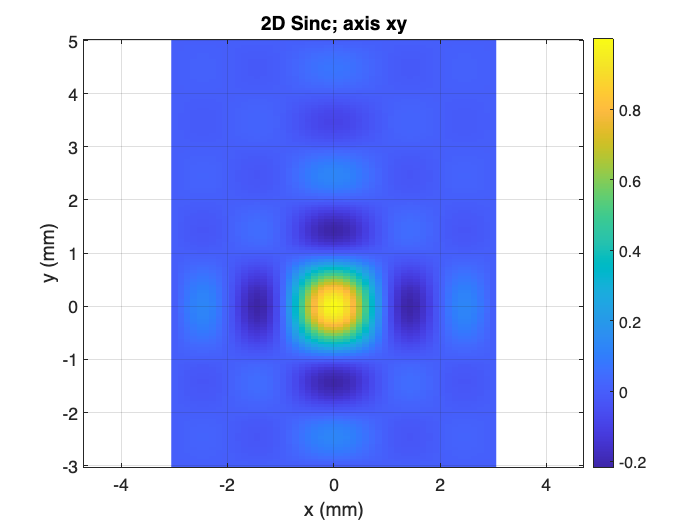

axis('xy')
title('2D Sinc; axis xy')

See also `axis('square')` and `axis('off')` -- useful options for adjusting the image display

Try `contour`, `surf`, and `mesh` to plot these data

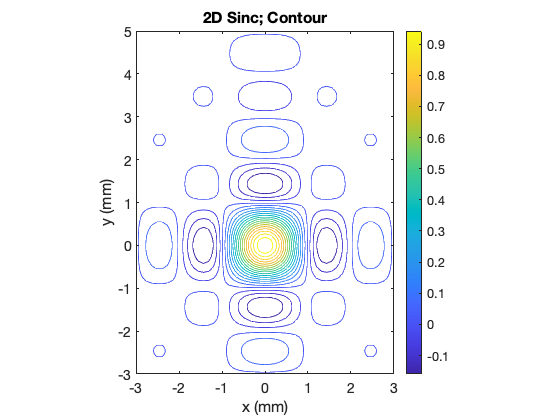

figure(2)
contour(x,y,f,20), colorbar
xlabel('x (mm)'), ylabel('y (mm)'),
title('2D Sinc; Contour'), axis('equal')

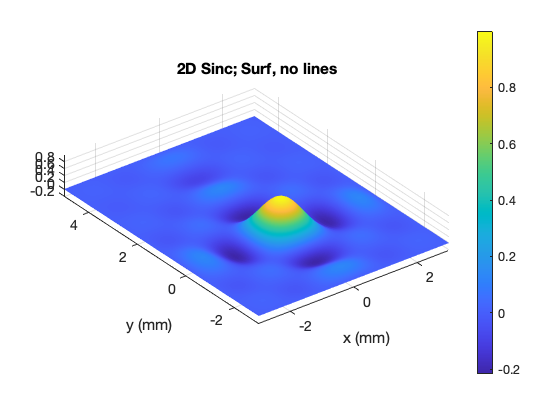

figure(3)
surf(x,y,f,'LineStyle','none', 'FaceColor','interp'), colorbar
xlabel('x (mm)'), ylabel('y (mm)'),axis('equal')
title('2D Sinc; Surf, no lines')

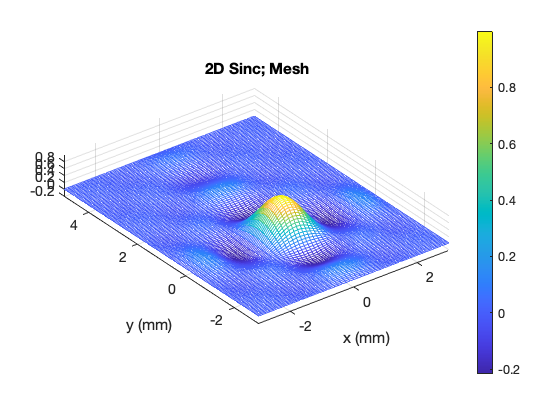

figure(4)
mesh(x,y,f), colorbar
xlabel('x (mm)'), ylabel('y (mm)'),axis('equal')
title('2D Sinc; Mesh')

% note that the 3D plots can be rotated by hand (select option in menu), or
% using the 'view' command

## 2D complex exponential

Again, it is straightfoward to extend our definition of the complex exponential function to 2D.

$\displaystyle
f(x,y) = \exp\left[2\pi i\left(x\nu_x+y\nu_y\right)\right]$, where $\nu_x$ and $\nu_y$ are spatial frequencies in the $x$ and $y$ directions, respectively

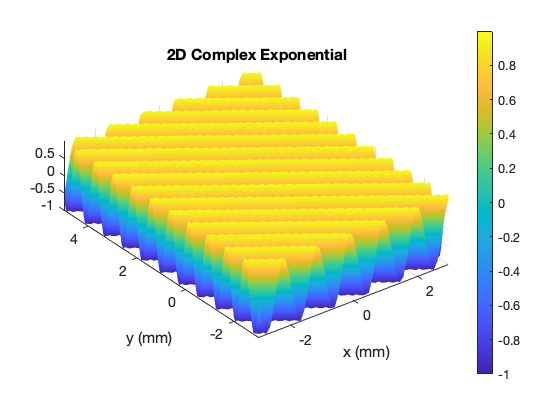

% MDD try changing frequencies in each direction
nu_x = 0.95;
nu_y = 1.3;


f = exp(1i*2*pi*(nu_x*x2+nu_y*y2));
figure(1);
surf(x,y,real(f),'LineStyle','none', 'FaceColor','interp'), colorbar
xlabel('x (mm)'), ylabel('y (mm)'),
axis('xy'), axis('equal')
title('2D Complex Exponential')

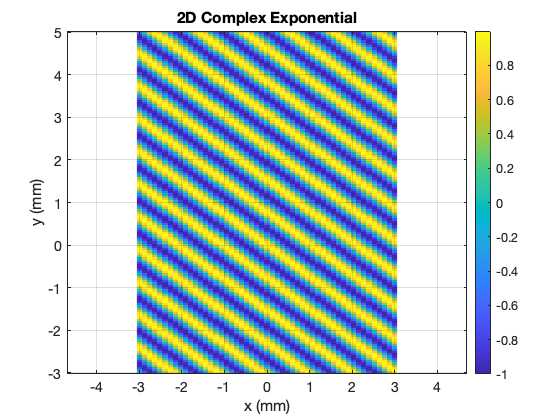

figure(2);
imagesc(x,y,real(f)), colorbar
xlabel('x (mm)'), ylabel('y (mm)'),
axis('xy'), axis('equal')
title('2D Complex Exponential')

## RGB and pseudocolor, and saving and loading data

Matlab can also read and write most common formats. For example, read in this color jpeg image of a chess piece.

IMG_RGB = imread('Chess_piece.jpg');

size(IMG_RGB)

ans =    594.0000e+000   350.0000e+000     3.0000e+000


Note the 3rd dimension. This is an RGB (red, green, blue) color encoding, to the first image is red intensity, the second is green intensity, and the third is blue intensity. 

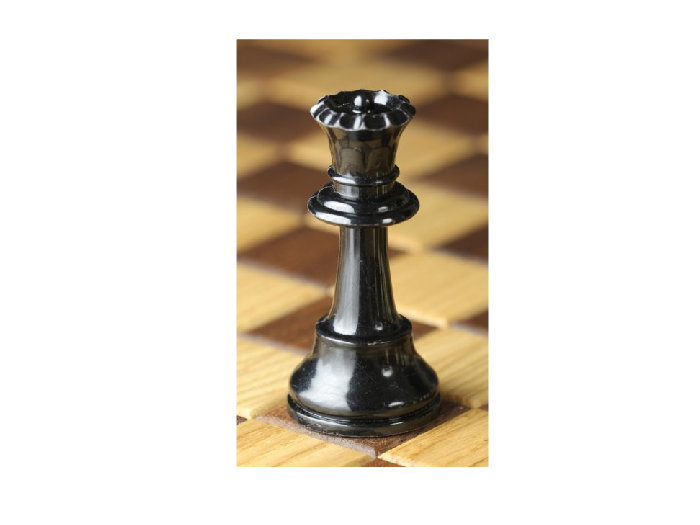

figure(1)
imagesc(IMG_RGB), axis('equal'), axis('off')

In medical imaging, image intensity is usually a scalar value and then we present the image with a gray scale or perhaps a pseudocolor scale

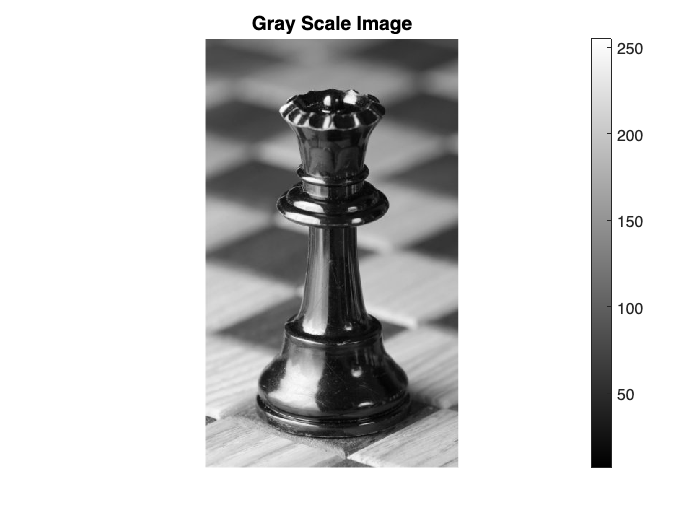

IMG_gray = rgb2gray(IMG_RGB);
figure(2)
imagesc(IMG_gray), colormap(gray), colorbar, axis('equal','off')
title('Gray Scale Image')

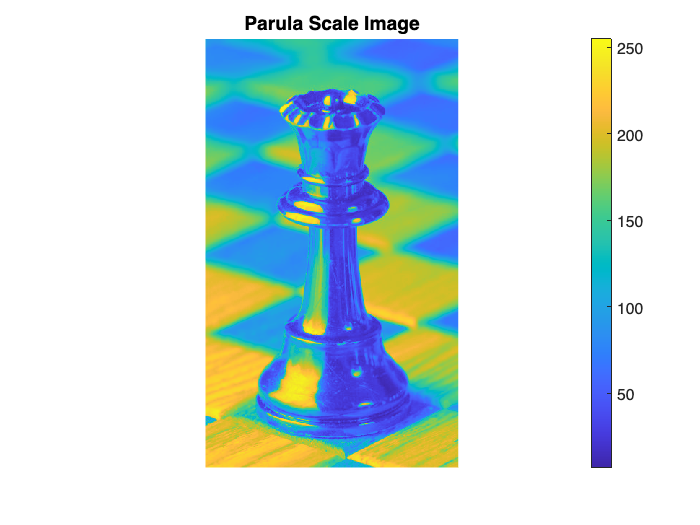

figure(3)
imagesc(IMG_gray), colorbar, axis('equal','off')
title('Parula Scale Image')

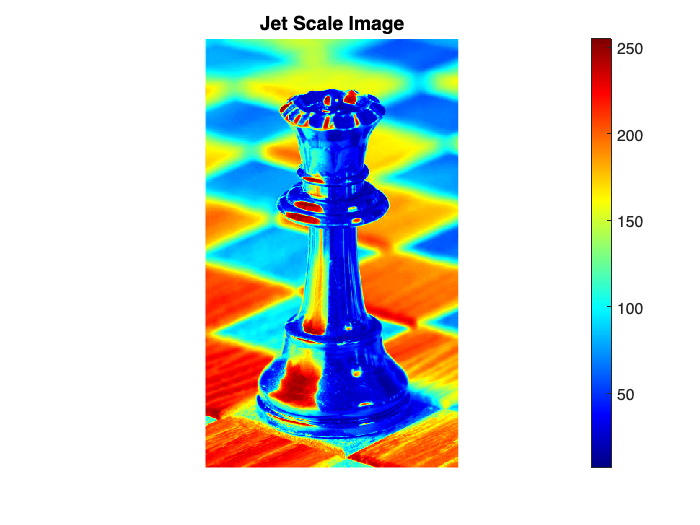

figure(4)
imagesc(IMG_gray), colorbar, colormap(jet), axis('equal','off')
title('Jet Scale Image')

Pseudocolor is normally frowned upon in medical imaging, but we sometimes use it to highlight particular information. Be careful though, results can be misleading. 